# **Introductory script illustrating wavefront-based tree shrew optics**

*This script compares the wavefront-based tree shrew optics model to tree shrew optics to the Gaussian-PSF model*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# **Step 1.** Generate the Gaussian-PSF based TreeShrew optics model

% Default tree shew optics
theDefaultOI = oiTreeShrewCreate('name', 'default optics');

% Lets see the default values of the treeshrew optics
defaultOpticsParams = opticsTreeShrewDefaultParams()

defaultOpticsParams = struct with fields:
                opticsType: 'gaussian psf'
    inFocusPSFsigmaMicrons: 7
             focalLengthMM: 4.3500
           pupilDiameterMM: 3


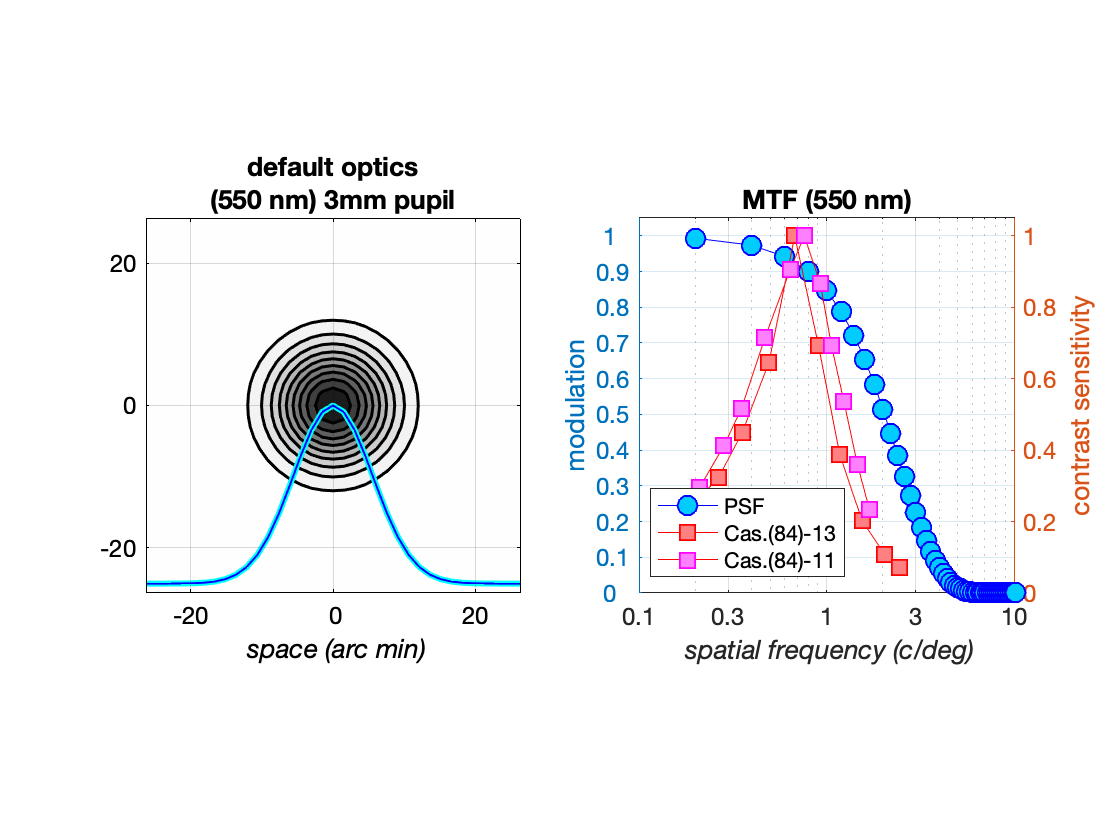


% Visualize the PSF at 550 nm
visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOptics(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData', csfTreeShrewFromPaper('casagrande84'));

# **Step 2.** Generate the wavefront-aberration based TreeShrew optics model

theWVFOI = oiTreeShrewCreate('opticsType', 'wvf', ...
    'name', 'wvf optics');

pupilPlaneSizeMM = 11.7905

pupilPlaneSizeMM = 12.0853

pupilPlaneSizeMM = 12.3801

pupilPlaneSizeMM = 12.6748

pupilPlaneSizeMM = 12.9696

pupilPlaneSizeMM = 13.2644

pupilPlaneSizeMM = 13.5591

pupilPlaneSizeMM = 13.8539

pupilPlaneSizeMM = 14.1487

pupilPlaneSizeMM = 14.4434

pupilPlaneSizeMM = 14.7382

pupilPlaneSizeMM = 15.0329

pupilPlaneSizeMM = 15.3277

pupilPlaneSizeMM = 15.6225

pupilPlaneSizeMM = 15.9172

pupilPlaneSizeMM = 16.2120

pupilPlaneSizeMM = 16.5068

pupilPlaneSizeMM = 16.8015

pupilPlaneSizeMM = 17.0963

pupilPlaneSizeMM = 17.3911

pupilPlaneSizeMM = 17.6858

pupilPlaneSizeMM = 17.9806

pupilPlaneSizeMM = 18.2753

pupilPlaneSizeMM = 18.5701

pupilPlaneSizeMM = 18.8649

pupilPlaneSizeMM = 19.1596

pupilPlaneSizeMM = 19.4544

pupilPlaneSizeMM = 19.7492

pupilPlaneSizeMM = 20.0439

pupilPlaneSizeMM = 20.3387

pupilPlaneSizeMM = 20.6335

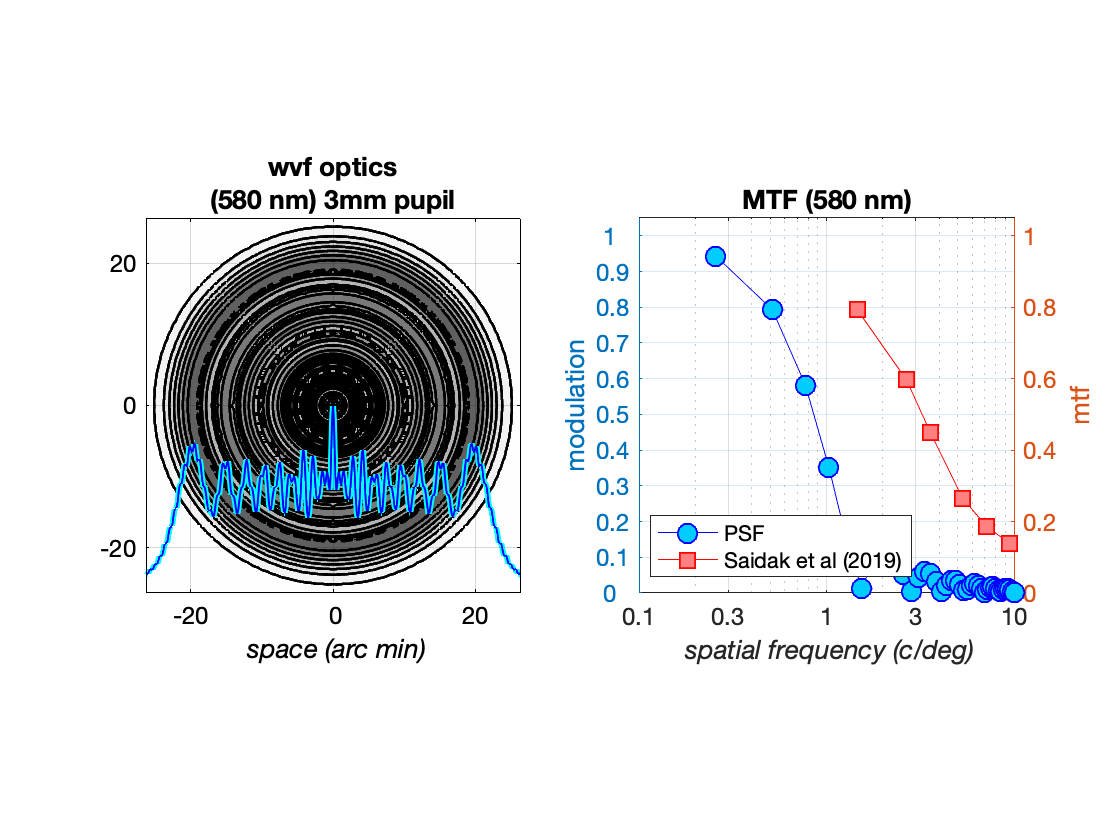

visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOptics(theWVFOI, 580, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));